# Actividad 3 (Evaluación)

## **Instituto Tecnológico de Estudios Superiores de Monterrey**

## **TE3001B.101**

## Fundamentación de Robótica

## Gpo 101

Profesor:

Alfredo García Suárez 

Alumnos:

Daniela Berenice Hernández de Vicente    A01735346

Fecha: 03 de Marzo del 2023

En este código se visualiza la configuración para obtener el vector de velocidades lineales y angulares del siguiente robot manipulador (Robot Scara de 3 GDL) :

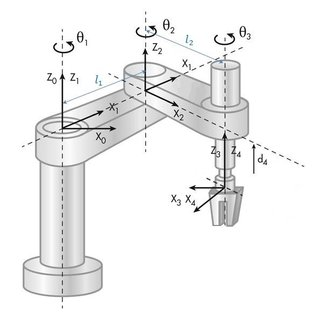

En esta primera parte del código lo que se hace es primero limpiar la pantalla para que cada que se ejecute el código se tenga cada variable limpia y sin datos previamente cargados.

Posteriormente se realiza una declaración de las variables a utilizar, también nos sirve para declarar el tipo de articulación a utilizar, el número de grados de libertad con los que nuestro robot cuenta (siendo en este caso 3).

De igual manera se crean los vectores de coordenadas y de velocidades de forma generalizadas.

%Limpieza de pantalla
clear all
close all
clc
%Declaración de variables simbólicas
syms th1(t) th2(t) th3(t) t l1 l2 q
%Configuración del robot, 0 para junta rotacional, 1 para junta prismática
RP=[0 0 0];
%Creamos el vector de coordenadas articulares
Q= [th1, th2 th3];
%disp('Coordenadas generalizadas');
%pretty (Q);
%Creamos el vector de velocidades generalizadas
Qp= diff(Q, t);
%disp('Velocidades generalizadas');
%pretty (Qp);
%Número de grado de libertad del robot
GDL= size(RP,2);
GDL_str= num2str(GDL);

A continuación se configuran las matrices.

Para dicha configuración existen dos formas de realizarse, de manera rotacional y prismática.

Por lo que las matrices de rotación que se utilizarán son las siguientes:


%Articulación 1 
%Posición de la articulación 1 respecto a 0
P(:,:,1)= [l1*cos(th1); l1*sin(th1);q];
%Matriz de rotación de la junta 1 respecto a 0
R(:,:,1)= [cos(th1) -sin(th1)  0;
           sin(th1)  cos(th1)  0;
           0         0         1];
%Articulación 2
%Posición de la articulación 2 respecto a 1
P(:,:,2)= [l2*cos(th2); l2*sin(th2);0];
%Matriz de rotación de la junta 1 respecto a 0
R(:,:,2)= [cos(th2) -sin(th2)  0;
           sin(th2)  cos(th2)  0;
           0         0         1];

%Articulación 2
%Posición de la articulación 2 respecto a 1
P(:,:,3)= [cos(th3); sin(th3);0];
%Matriz de rotación de la junta 1 respecto a 0
R(:,:,3)= [cos(th3) -sin(th3)  0;
           sin(th3)  cos(th3)  0;
           0         0         1];


Ahora bien para poder encontrar el valor de las posiciones dentro de nuestros sistemas, es necesario tomer en cuenta que en esta ocasión nuestro marco de referencia será entorno al eje z, esto es para que se pueda modelar cada una de las articulaciones de todo el sistema.


%Creamos un vector de ceros
Vector_Zeros= zeros(1, 3);
%Inicializamos las matrices de transformación Homogénea locales
A(:,:,GDL)=simplify([R(:,:,GDL) P(:,:,GDL); Vector_Zeros 1]);
%Inicializamos las matrices de transformación Homogénea globales
T(:,:,GDL)=simplify([R(:,:,GDL) P(:,:,GDL); Vector_Zeros 1]);
%Inicializamos las posiciones vistas desde el marco de referencia inercial
PO(:,:,GDL)= P(:,:,GDL); 
%Inicializamos las matrices de rotación vistas desde el marco de referencia inercial
RO(:,:,GDL)= R(:,:,GDL); 

Posteriormente se crea un vector inicializado en ceros, nuestras matrices  de tranformación homegénea globales y locales.


for i = 1:GDL
    i_str= num2str(i);
   %disp(strcat('Matriz de Transformación local A', i_str));
    A(:,:,i)=simplify([R(:,:,i) P(:,:,i); Vector_Zeros 1]);
   %pretty (A(:,:,i));
   %Globales
    try
       T(:,:,i)= T(:,:,i-1)*A(:,:,i);
    catch
       T(:,:,i)= A(:,:,i);
    end
    %disp(strcat('Matriz de Transformación global T', i_str));
    T(:,:,i)= simplify(T(:,:,i));
    %pretty(T(:,:,i))
    RO(:,:,i)= T(1:3,1:3,i);
    PO(:,:,i)= T(1:3,4,i);
    %pretty(RO(:,:,i));
    %pretty(PO(:,:,i));
end

En el ciclo for enseñado anteriormente se ingresan las matrices de cada una de las articulaciones de manera global  T y local A.


%Calculamos el jacobiano lineal de forma diferencial
disp('Jacobiano lineal obtenido de forma diferencial');
%Derivadas parciales de x respecto a th1 y th2
Jv11= functionalDerivative(PO(1,1,GDL), th1);
Jv12= functionalDerivative(PO(1,1,GDL), th2);
Jv13= functionalDerivative(PO(1,1,GDL), th3);
%Derivadas parciales de y respecto a th1 y th2
Jv21= functionalDerivative(PO(2,1,GDL), th1);
Jv22= functionalDerivative(PO(2,1,GDL), th2);
Jv23= functionalDerivative(PO(2,1,GDL), th3);
%Derivadas parciales de z respecto a th1 y th2
Jv31= functionalDerivative(PO(3,1,GDL), th1);
Jv32= functionalDerivative(PO(3,1,GDL), th2);
Jv33= functionalDerivative(PO(3,1,GDL), th3);


Se crea cada una de las matrices jacobianas lineales de forma diferencial correspondientes a cada una de las articulaciones con respecto a theta1 y theta2.


%Creamos la matríz del Jacobiano lineal
jv_d=simplify([Jv11 Jv12 Jv13;
               Jv21 Jv22 Jv23;
               Jv31 Jv32 Jv33]);
%pretty(jv_d);
%Calculamos el jacobiano lineal de forma analítica
Jv_a(:,GDL)=PO(:,:,GDL);
Jw_a(:,GDL)=PO(:,:,GDL);


Al tener cada uno de los jaconbianos, procedemos a crear una matriz del jacobiano lineal con cada uno de los elementos anteriormente mencionados, posteriomente procedemos a calcular el jacobiano lineal de manera analítica.


for k= 1:GDL
    if RP(k)==0 
       %Para las juntas de revolución
        try
            Jv_a(:,k)= cross(RO(:,3,k-1), PO(:,:,GDL)-PO(:,:,k-1));
            Jw_a(:,k)= RO(:,3,k-1);
        catch
            Jv_a(:,k)= cross([0,0,1], PO(:,:,GDL));%Matriz de rotación de 0 con respecto a 0 es la Matriz Identidad, la posición previa tambien será 0
            Jw_a(:,k)=[0,0,1];%Si no hay matriz de rotación previa se obtiene la Matriz identidad
         end
     else
%         %Para las juntas prismáticas
        try
            Jv_a(:,k)= RO(:,3,k-1);
        catch
            Jv_a(:,k)=[0,0,1];
        end
            Jw_a(:,k)=[0,0,0];
     end
 end    
Jv_a= simplify (Jv_a);
Jw_a= simplify (Jw_a);
%disp('Jacobiano lineal obtenido de forma analítica');
%pretty (Jv_a);
%disp('Jacobiano ángular obtenido de forma analítica');
%pretty (Jw_a);


En el ciclo for anteriormente visto se genera con el fin de obtener el jacobiano ángular y lineal de manera analítica tanto para las juntas de revolución como para las juntas primáticas.

disp('Velocidad lineal obtenida mediante el Jacobiano lineal');
V=simplify (Jv_a*Qp');
pretty(V);
disp('Velocidad angular obtenida mediante el Jacobiano angular');
W=simplify (Jw_a*Qp');
pretty(W);

Ya por último procedemos a imprimir las velocidades angulares y lineales obtenidas mediante el Jacobiano angular y lineal, de igual forma se utiliza la función simplify para observar cada uno de los resultados de manera simplificada y pretty para ver de una forma más estética y eficiente.